# Assignment - EE4190 Introduction to Modern Radar

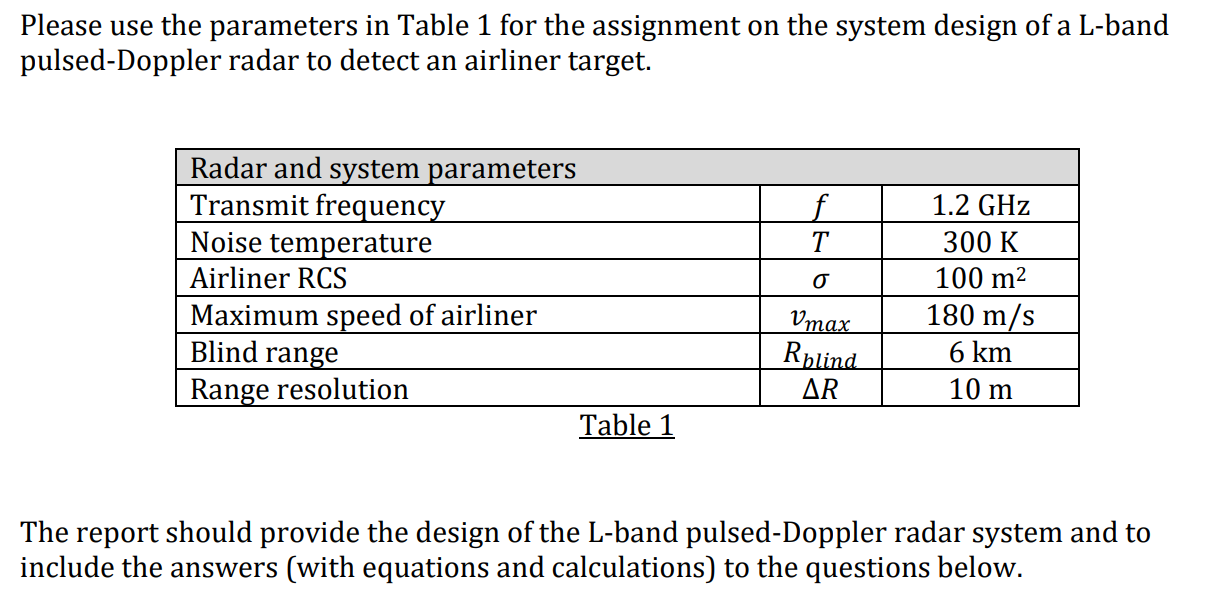

db = @(abs) 10*log(abs)/log(10);
%Given data
range_resolution = 10; v_max = 180; sigma = 100; boltzmann_constant = 1.38064e-23; blind_range = 6e3;
frequency = 1.2e9; wavelength = 3e8/frequency; T = 300;
tau = 2*range_resolution/3e8, bandwidth = 1/tau, prf=v_max*4/wavelength, pri=1/prf, Tx = blind_range*2/3e8, transmit_tau =Tx

tau = 6.6667e-08

bandwidth = 15000000

prf = 2880

pri = 3.4722e-04

Tx = 4.0000e-05

transmit_tau = 4.0000e-05

%Data we choose
Pt = db(500e3); Gr =20; Gt=20; 
receiver_gain= 25; F = 5; M = 10;  

#### *A) Please provide a brief explanation of the following parameters and their values (Suggest reasonable values and state any assumption, if any ) in the design*

- **Transmit Power**

We are designing a radar that can detect and display the presence of an aircraft near the terminal area. The maximum unambigous range $R_{\mathrm{un}} =\frac{c\cdot \;\mathrm{PRI}}{2}=5\ldotp 2\times {10}^4 =52\mathrm{km}$ . It means that we don't need a very strong transmit power.

$P_t =1\textrm{KW}=10\cdot \log \left(1\times {10}^3 \right)=30\textrm{dBW}\;\;$ , With a antenna Gain of 20dBi we can achieve level of SNR more than 7dB with a single pulse within the unambious range.

However, when Pt becomes 1KW the power that return  is $4\ldotp 3\times {10}^{-15} W$ which is so small. Therefore, I used $P_t =500\mathrm{KW}$. If we are considering coherent integration of 10, then the $P_r =13\mathrm{nW}$

        2. **Transmit antenna gain**

The general antenna gain was aound 20 ~ 30dB. I used the value 20dB.


$$G_T =20\textrm{dBi}$$
 

        3. **Receive antenna gain**

I used the same value as the transmit antenna gain. 20dB


$$G_r =20\textrm{dBi}$$


        4. **Pulses width**

Range Resolution 10 m : The Range resolution, depends on the pulse width $\frac{c\tau }{2}$, Therefore, the pulse width is $\longrightarrow$$\tau =66\ldotp 667\times {10}^{-9}$ and that is $66\ldotp 7\;\textrm{ns}$. 

        5. **Signal bandwidth**

The signal Bandwidth $B=\frac{1}{\tau }=\frac{1}{66\ldotp 7\;\mathrm{ns}}=14\ldotp 993\times {10}^6 \mathrm{Hz}\approx 15\mathrm{Mhz}$

        6. **Pulse repetition interval**

Maximum speed of airliner $v_{\mathrm{max}} =180\;\frac{m}{s}$  , The maximum unambious velocity is $\frac{\lambda \cdot \textrm{PRF}}{4}=180\;$. Therefore $\frac{c}{f}\cdot \frac{\textrm{PRF}}{4}=\frac{3\times {10}^8 }{1\ldotp 2\times {10}^9 }\cdot \frac{\textrm{PRF}}{4}=180\;$  Therefore, $\textrm{PRF}=2880\;\textrm{Hz}\;$,


$$\mathrm{PRI}\;=\frac{1}{2880}=3\ldotp 4722\times {10}^{-4} =347\ldotp 22\;\mathrm{us}$$


        7. **Pulse repetition frequency**

Stated Above. $\textrm{PRF}=2880\;\textrm{Hz}\;$

        8. **Receiver Gain**


$$\to 25\mathrm{dBi}$$


        9. **Noise Figure**


$$\to F=5\mathrm{dB}$$


        10. **Number of pulses for coherent integration**


$$\to M\;=\;10$$


###         $a$. **Transmit time**

**Blind Range **$6\;\mathrm{km}$ : If the signal has a transmission time of $T_x$ , the receiver can only receive siganl after time $T_x$ therefore the minimum distant the radar can detect is $\frac{{\mathrm{cT}}_x }{2}$.     Then $\frac{\left(\;3\times {10}^8 \;\right)\;\times T_x \;}{2}=6000\;m$, Therefore, the $T_x =40\;\mathrm{us}\;$, The transmit time is $40\;\mathrm{us}$

#### B) with the Design parameters in part (a), please provide the maximum range of the airliner that can be detected by the radar with SNR of at least 13dB ?

The Radar Equation 

#### $P_{r\;} =\frac{P_t G_t }{4\pi R^2 }\times \frac{\sigma A_e }{4\pi R^2 }=\frac{P_t G_t \sigma A_e }{{\left(4\pi \right)}^2 \;R^4 }$         $\mathrm{but},\frac{4\pi A_e }{\lambda^2 }=G_r \;\mathrm{Therefore},A_e =\frac{\lambda^2 G_r }{4\pi }$   $P_r =$$\frac{P_t G_t G_r \sigma \lambda^2 }{{\left(4\pi \right)}^3 \;R^4 }$, $\mathrm{SNR}=\frac{\mathrm{Singal}}{\mathrm{Noise}}=\frac{P_T G_T G_r \sigma \lambda^2 }{{\left(4\pi \right)}^3 R^4 \mathrm{kTBF}}$

#### $\mathrm{SNR}\;\ge 13\;,\frac{P_T G_T G_r \sigma \lambda^2 }{{\left(4\pi \right)}^3 R^4 \textrm{kTBF}}\ge {10}^{1\ldotp 3} \;$ find R

SNR = @(range) Pt + Gt + Gr + db(sigma) + 2.*db(wavelength) -3.*db(4*pi) -4.*db(range) + db(M) + db(bandwidth*transmit_tau) - db(boltzmann_constant) - db(T) - db(bandwidth) - F;
fsolve(@(range) SNR(range)-13,[1e-6 100e4])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



ans = 	1.0e+05 *

    3.9402    3.9402


**The maximum Range is **$394\textrm{Km}$

#### C) Given the number of pulses selected for coherent intergration inf the design, please explain why it cannot be indefinitely increase to achieve a much higer target SNR ?

The larger the number of pulses integrated the greater SNR. However, the effectiveness of coherent integration drops over the integration time. Suppose we have a target that is moving and we are sending multiple pulses over time. Then the first return pulse from the target has a different phase from the last return pulse. If the number of pulses is small then the change is insignificant, but large then drops down the coherent integration gain. This is called spatial decorrelation problem.

#### D) Draw a complete block diagram of L-band pulsed Doppler Radar